% Create tranfer function.
s=tf('s');
G0=6/(s*(s^2+4*s+6))


G0 =
 
          6
  -----------------
  s^3 + 4 s^2 + 6 s
 
Continuous-time transfer function.



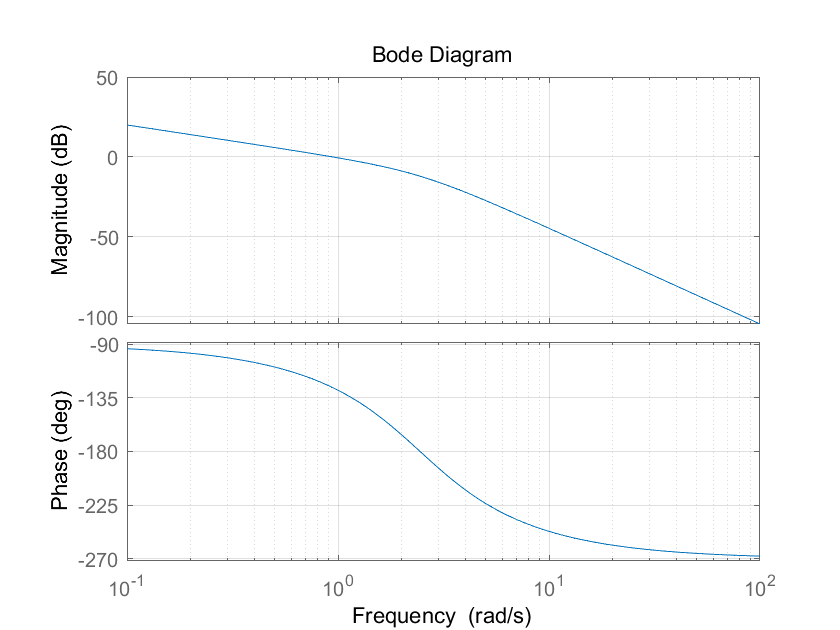


% Create a list of number with 50 numbers 
% arrange evenly between 10^0 and 10^4 in log space
w=logspace(-1,2,100);

% Draw the bode chart of the system
bode(G0,w);
grid on;


% Am --- Ampitude margin
% Pm --- Phase margin
% Wc --- Cutoff frequency
% Wg --- Traverse frequency
[Am,Pm,Wc,Wg]=margin(G0);

fprintf('The ampitude margin of the system is %f dB\n', 20*log(Am));

The ampitude margin of the system is 27.725887 dB


fprintf('\tThe cutoff frequency is %f rad/s\n', Wc);

	The cutoff frequency is 2.449490 rad/s


fprintf('The phase margin of the system is %f degrees\n', Pm);

The phase margin of the system is 53.515926 degrees


fprintf('\tThe traverse frequency is %f rad/s\n', Wg);

	The traverse frequency is 0.944401 rad/s
